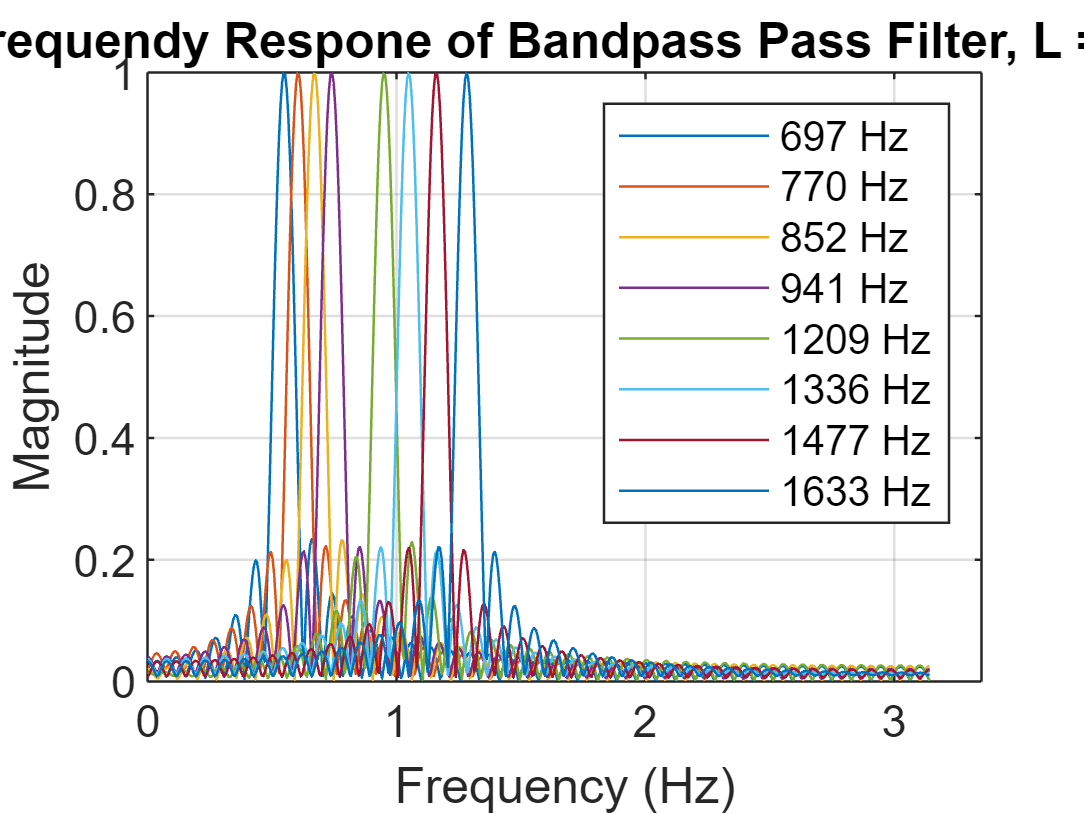

%L = 80, Freq = 8000Hz
fb= [697 770 852 941 1209 1336 1477 1633];
a = dtmfdesign(fb, 80, 8000);
title('Frequendy Respone of Bandpass Pass Filter, L = 80');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
legend(arrayfun(@(f) sprintf('%d Hz', f), fb, 'UniformOutput', false));


%{
%f (it is in two parts)----------------------
%(f)Finding minimum length L (part 1)
fb = [697 770 852 941 1209 1336 1477 1633];
fs = 8000;
L = 2; % initial value for L
done = 0;

while (~done)
    k = 0;
    L = L + 1;
    hh = []; % initiate
    for i = 1:length(fb)
        nn = 0:(L-1);
        hh(:, i) = cos(2 * pi * fb(i) * nn / fs); % filter impulse response
        ww = 0:pi/1000:pi;
        HH = freqz(hh(:, i), 1, ww);
        HH1 = freqz((1 / max(abs(HH))) * hh(:, i), 1, ww);
        % frequency response of filter with maximum value equal to one
        for j = 1:length(fb)
            z = round(2 * (fb(j) / fs) * 1000);
            if abs(HH1(z)) < 0.25 % stop-band proportion 25%
                k = k + 1;
            end
            if k == 56
                done = 1;
            end
        end
    end
end

L = 88 % minimum L = 88

% (f) Evaluation L whether satisfies the demand or not (part 2)
L = 88;
fb = [697 770 852 941 1209 1336 1477 1633];
w_loca = [1395 1541 1705 1883 2419 2673 2955 3267];
% the location for each eight frequencies’ peak value
hh = zeros(L, length(fb));
plot(0:0.001:pi, 0.25)
hold on
for i = 1:length(fb)
    nn = 0:(L-1);
    hh(:, i) = cos(2 * pi * fb(i) * nn / fs); % filter impulse response
    ww = 0:pi/8000:pi;
    HH = freqz(hh(:, i), 1, ww);
    HH1 = freqz((1 / max(abs(HH))) * hh(:, i), 1, ww);
    stem(ww(w_loca), abs(HH1(w_loca)));
    % stem the specific point for each eight filters
    hold on;
    title('Zoom in for evaluation')
    xlabel('Digital Frequency (ww)'); ylabel('Magnitude');
end
%}